clc
clear
file_num = 4;
root_dir = "C:\Users\olive\OneDrive - University of Surrey\individual project\data\raw_data";
testdate = "26_04_22";
freq = 1/333;

### Qualsis import

path = root_dir + "/" + testdate + "/qualsis_data/*Ollie*.mat";
file_names = dir(path)

file_names = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


current_file = file_names(file_num);
data = load(strcat(current_file.folder, '\', current_file.name));
fnames = fieldnames(data);
data = data.(fnames{1});

trajectories = data.Trajectories.Unidentified.Data;
qualsis_time = (1:1:data.Frames)/data.FrameRate;

num_points = size(trajectories)

num_points =            7           4        3000


meancol = [];
stdcol = [];
ncol = [];
rmscol = [];
for i = 1:5
    traj=squeeze(trajectories(i,4,:));
    meancol(i) = mean(traj, 'omitnan');
    stdcol(i) = std(traj, 'omitnan');
    ncol(i) = length(rmmissing(traj));
    rmscol(i) = rms(traj, 'omitnan');
end
summary = [meancol',stdcol',ncol', rmscol']

summary = 	1.0e+03 *

    0.0011    0.0004    2.2000    0.0012
    0.0009    0.0004    2.2010    0.0009
    0.0010    0.0005    2.2040    0.0011
    0.0008    0.0004    2.1870    0.0009
    0.0015    0.0007    2.1990    0.0016


summary(:,5) = summary(:,1) .* summary(:,3);
sum(summary(:,5))/sum(summary(:,3))

ans = 1.0554

clf
v_col = [];
num_points = size(trajectories)

num_points =           12           4        1672


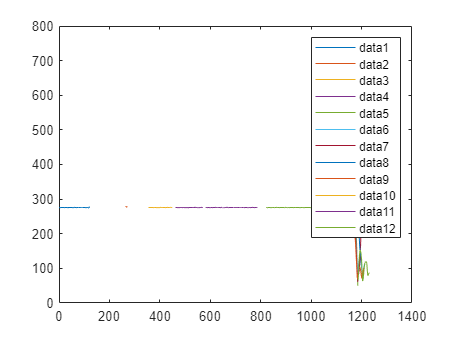

for i = 1:num_points
   v_col = [v_col squeeze(trajectories(i,3,:))];
end
plot(v_col)
legend

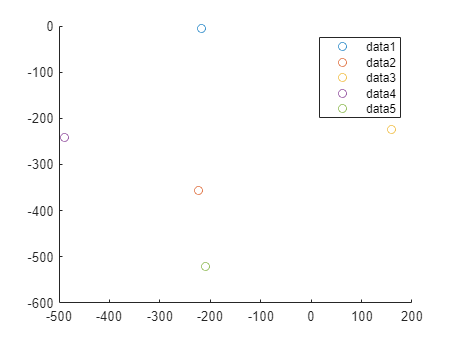

first_instance =1141;
clf
hold on
p1 =5;
p2 =6;
p3 =7;
p4 =8;
p5 =9;
scatter3(trajectories(p1,1,first_instance), trajectories(p1,2,first_instance), trajectories(p1,3,first_instance))
scatter3(trajectories(p2,1,first_instance), trajectories(p2,2,first_instance), trajectories(p2,3,first_instance))
scatter3(trajectories(p3,1,first_instance), trajectories(p3,2,first_instance), trajectories(p3,3,first_instance))
scatter3(trajectories(p4,1,first_instance), trajectories(p4,2,first_instance), trajectories(p4,3,first_instance))
scatter3(trajectories(p5,1,first_instance), trajectories(p5,2,first_instance), trajectories(p5,3,first_instance))
legend
hold off

nose = 1;
tail = 5;
left = 4;
right =3;
mid = 2;

point_order = [nose,tail,left,right,mid];
s = size(trajectories)

s =           12           4        1672


if s(1) > 5
    trajectories = trajectories(p1:p5,:,:);
end

% interpolate
rebase_time = @(x,f) freq:freq:1/f*length(x);
rebase_qualsis = @(x) interp1(1/120:1/120:(1/120*length(x)), x, rebase_time(x,120));
qualsis_data = [];
num_points = 5;
for point_store = 1:num_points*3
    point = floor((point_store-1)/3) + 1;
    axis = mod(point_store - 1, 3) + 1;
    qualsis_data(:, point_store) = rebase_qualsis(squeeze(trajectories(point_order(point),axis,:)));
end

### UAV import

folder = root_dir + "/" + testdate + "/uav_data/*.csv";

files = dir(folder);
display(files)

files = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



file_name = files(file_num).folder + "/" + files(file_num).name;
% file = importdata(file_name,',');
% uav_data = file.data(file.data(:,1) < 2000000, :);

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["time", "gx", "gy", "gz", "ax", "ay", "az", "ign"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
uav_data = readtable(file_name, opts);

%interpolate
rebase_uav = @(x) interp1(uav_data{:,1}./1e6, x, rebase_time(x,333));
uav_data_interp = [];
for col = 2:7
    uav_data_interp(:, col-1) = rebase_uav(uav_data{:,col});
end

clf
axis = 1

axis = 1

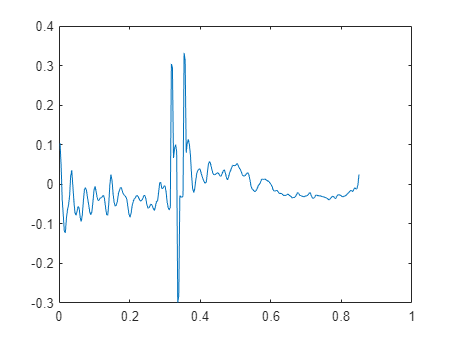

start = 700;
plot(rebase_time(uav_data_interp(start:end,axis), 333),uav_data_interp(start:end,axis))

rms(uav_data_interp(start:end,axis),'omitnan')

ans = 0.0602

### Combine & Export

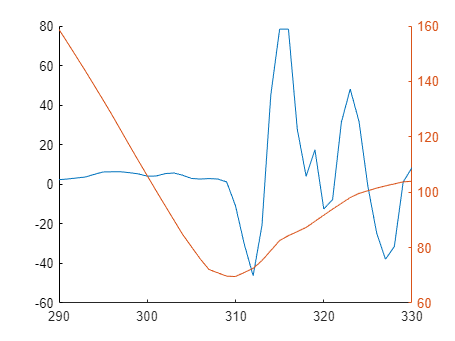

scale_offset = 290;
scale = 330;
qualsis_point = 6;
fine = 7;
coarse = 270;
ultra_coarse = 2700;
tune = coarse + fine + ultra_coarse;
clf
xlim([scale_offset,scale])
hold("on")
plot(uav_data_interp(:,6))
q = qualsis_data(:, qualsis_point);
yyaxis right
plot(q(tune:end,:))
hold("off")

final = [];
for qual_i = 1:num_points*3
    final(:,qual_i) = qualsis_data(tune:length(uav_data_interp(:,1)) - 1 + tune, qual_i);
end
for uav_i = 1:6
    final(:,num_points*3+uav_i) = uav_data_interp(:,uav_i);
end

writematrix(final, file_num + "_complete_data.csv")